# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.3 三维绘图

#### 2.3.2  三维矢量场图

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

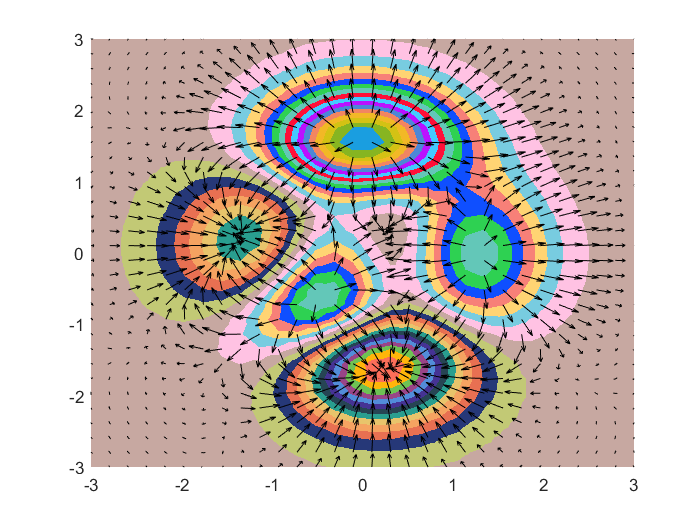

clear;clc;
% 获取到颜色
[all_themes, all_colors] = GetColors();
% 产生数据
[X, Y, Z] = peaks(30);  
% 矢量场，曲面法线
[U, V, W] = surfnorm(X, Y, Z);  
% 箭头长度、颜色
quiver3(X, Y, Z, U, V, W, 0.5, 'k');     
hold on
surf(X,Y,Z);   
xlim([-3, 3]);
ylim([-3, 3]);
colormap(all_colors(1:30, :));
%  网格线不显示
shading interp
hold off
view(0, 90);